# Coordinate System Transformations

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Building a robotic manipulator requires defining where each of its components are located in space, at all times. Each component will have an assigned coordinate system or frame. This script will introduce using coordinate systems and homogeneous transformation matrices for describing the position and orientation (or motion) of points (i.e., components) in cartesian space. At the end of this script, we will visualize the result of applying a homogenous transformation matrix to a defined point in space.

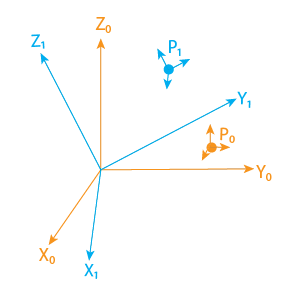

You will learn to construct transformation matrices to change between coordinate frames.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Introduction to Manipulators

A generic robotic manipulator is a series of links attached by joints to a base. They commonly also have an end-effector, where a tool such as a drill or camera is mounted. Links can be rigid or flexible. For simplicity of solving kinematic equations, it is assumed that links be treated as rigid bodies. This means the links can be considered to have infinite stiffness. Therefore, an applied load on the link will result in zero deflection of material:

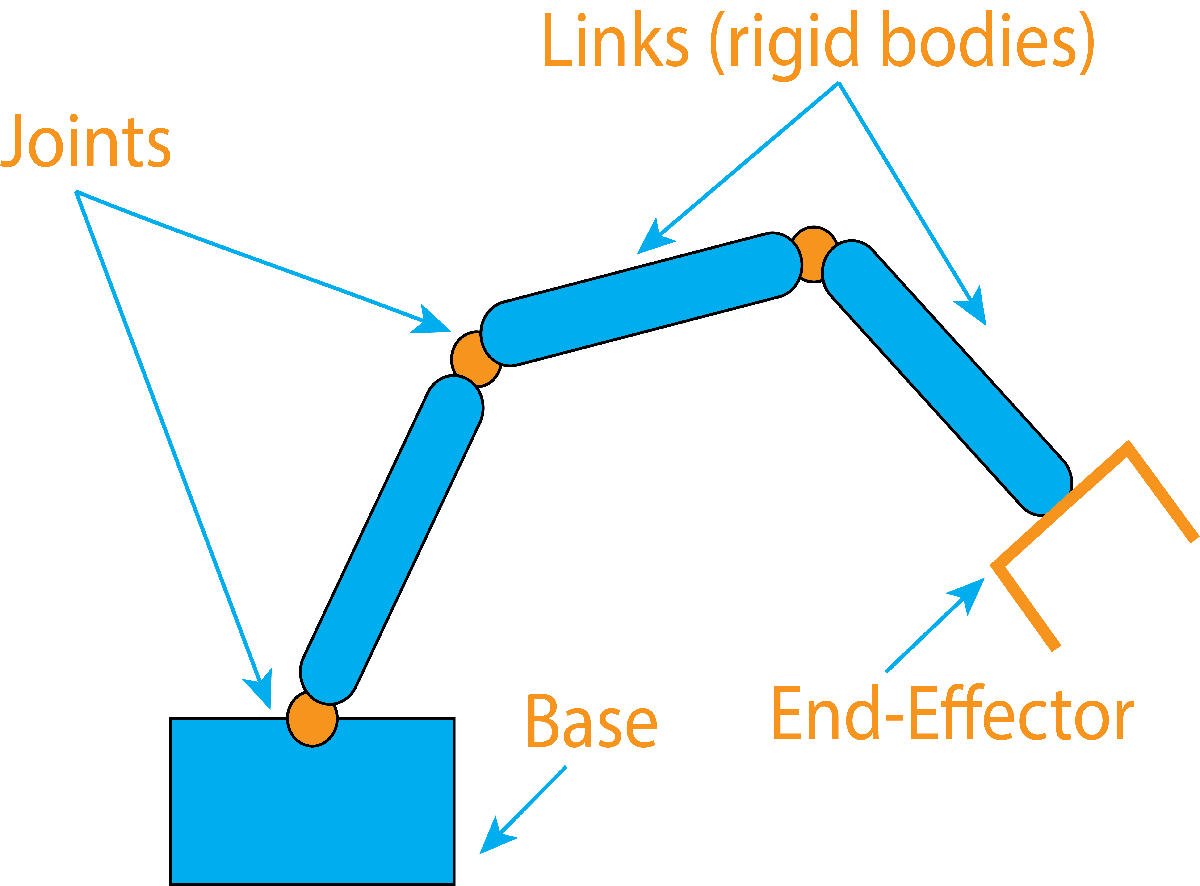

There are also many types of joints used in robotics. Revolute, cylindrical, prismatic and spherical joints are some of the most used. Each joint is represented by a varying number of degrees of freedom (DOF): 

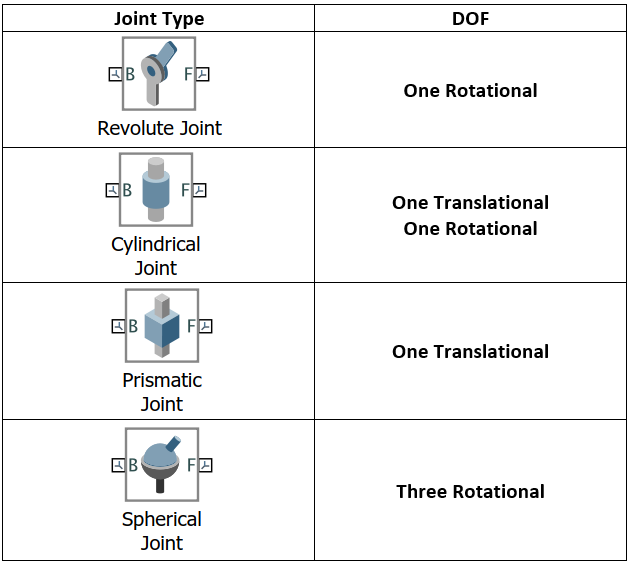

  **Pro-tip**. For visualization purposes, a revolute joint can be thought of as a mechanism that functions like a door hinge. More info on the other types of joints also used in MATLAB can be found [here](https://www.mathworks.com/help/sm/referencelist.html?type=block&category=multibody-dynamics&s_tid=CRUX_topnav).

## Coordinate Systems and Transformation Matrices

Let's consider the mechanics of a ***simplified*** human arm (from the shoulder to the hand). We could model that arm as a robotic manipulator that has three revolute joints (following the diagram below). Traditionally, robotic arms are attached to a base platform that provides the rigid attachment for the robot to move. The first joint is connected to the base, rotating about angle $\theta_1$. The second joint is a "shoulder" joint connecting the base and the first link, rotating about angle $\theta_2$. The third joint is an "elbow" joint connecting the first link and the second link, rotating about angle $\theta_3$. If we were to add a fourth joint to the end of the second link, it would be considered a "wrist" joint, connecting the second link to an end-effector, or hand. For the case of a robot manipulator that has three revolute joints, it is understood that it will have three rotational degrees of freedom (3DOF). If we added the fourth joint as mentioned above, the robot would have 4DOF. 

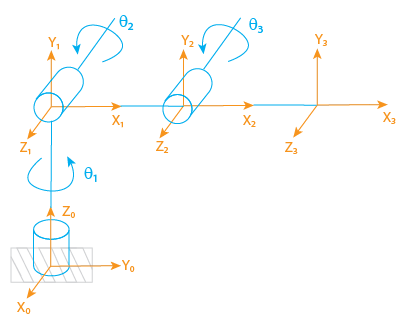

Each joint is associated with its own cartesian coordinate system. The first joint connected to the base rotates about $\theta_1 \;$from the base coordinate system$\;\left(x_0 \;,y_0 \;,z_0 \right)$ to the second joint coordinate system$\;\left(x_1 \;,y_1 \;,z_1 \right)$. Similarly for the next two joints rotating about $\theta_2$ and $\theta_3$, the coordinate systems need to be transformed in order to represent the location of the robot manipulator properly. Each joint coordinate system is specified by a pair of matrices $t$ and $R$, where $t$ is a 3x1 translation vector and $R$ is a 3x3 rotation matrix.

  **Pro-tip**.  More advanced robots allow for 6DOF or more. Often, they have a spherical "wrist" joint at the end-effector which provides an additional three more degrees of freedom. The addition of spherical joints may more closely represent a real human arm's joints, adding to the complexity.

### Coordinate Transformation: Translation

First, let us begin by understanding the translation vector. This is the amount the origin of frame $\left(x_1 \;,y_1 \;,z_1 \right)$ or {1} has translated with respect to frame $\left(x_0 \;,y_0 \;,z_0 \right)$ or {0}. In this case, the 3x1 translation vector or origin shift, $t_1^{0\;}$ is represented by $o$:

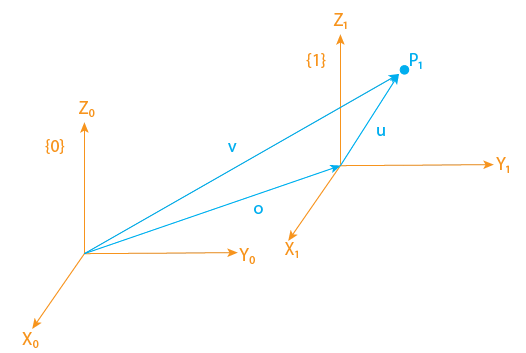

Point $p_1$is defined by its position vector, $u$. We can determine the position vector, $v$, of the point $p_0$ by adding the origin shift to the position vector in frame {1}. The position of point $p_0$ is represented by a 3x1 vector. Using vector mathematics, we can represent the translation with: 


$$\vec{v} =\vec{o} \;+\vec{u}$$


If we replace these vectors with our points of interest, we have:


$$\vec{p_0 } =\vec{o_1^0 } \;+\vec{p_1 }$$


  **Pro-tip**. Point $p_0$ is not a new point. Rather, it is a way of expressing the location of point $p_1$ with respect to another frame of reference. In other words, point $p_1$ with respect to frame {0} is equivalent to $p_0$.

** Demonstration**. Consider a given translated point $p_1$ and an origin shift of a coordinate system $o_1^0$. What would be the position of point $p_0$?

% Point o
o =  [3;4;5];

% Point p1
p1 = [1;2;1];

% Solving for point at (x0,y0,z0)
p0 = o + p1;

 

% Display Point p0
disp(string(['Point p1 with respect to frame {0}: ' 'p0 = ' '[' num2str(p0') ']']));

hold on

% Plot non-translated point p0
fig1 = plot3(p0(1),p0(2),p0(3));
fig1.Color = "red";
fig1.Marker = "*";
text(p0(1),p0(2),p0(3),'     p0');

% Plot translated point p1
fig2 = plot3(p1(1),p1(2),p1(3));
fig2.Color = "blue";
fig2.Marker = "*";
text(p1(1),p1(2),p1(3),'     p1');

% Axes setting for coordinate frames
ax1 = gca;
quiverSize = max([range(ax1.XLim) range(ax1.YLim) range(ax1.ZLim)])/5;

% Add coordinate frames to non-translated point    
t1 = quiver3(p0(1), p0(2), p0(3), 1, 0, 0, quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
t2 = quiver3(p0(1), p0(2), p0(3), 0, 1, 0, quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
t3 = quiver3(p0(1), p0(2), p0(3), 0, 0, 1, quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Add coordinate frames to translated point
t4 = quiver3(p1(1), p1(2), p1(3), 1, 0, 0, quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
t5 = quiver3(p1(1), p1(2), p1(3), 0, 1, 0, quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
t6 = quiver3(p1(1), p1(2), p1(3), 0, 0, 1, quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Add axes and legend info to plot
fig1.Parent.XLabel.String = "X (m)";
fig1.Parent.YLabel.String = "Y (m)";
fig1.Parent.ZLabel.String = "Z (m)";
fig1.Parent.XLim = [min(min(p0,p1))-1 max(max(p0,p1))+1];
fig1.Parent.YLim = [min(min(p0,p1))-1 max(max(p0,p1))+1];
fig1.Parent.ZLim = [min(min(p0,p1))-1 max(max(p0,p1))+1];
legend(ax1,{'','','X','Y','Z'})
view([46.91 35.45])
hold off
grid

### Coordinate Transformation: Rotation

Next, we will look at the rotation matrix. Compared to the translation example, we can see that the origin remains the same and the orientation shifts this time. If we rotate a frame $\left(x_1 \;,y_1 \;,z_1 \right)$ or {1} with respect to frame $\left(x_0 \;,y_0 \;,z_0 \right)$ or {0}, we need to apply a 3x3 rotation matrix, $R_0^1$.

If a point $p_0$ is to be measured from frame {1} with respect to frame {0}, the rotation is expressed as $\Rightarrow$$\vec{p_1 } =R_0^1 \cdot \vec{p_0 }$ where:

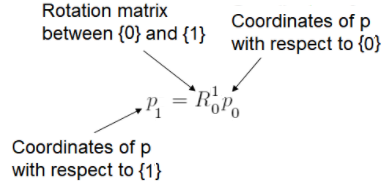

In order to create the rotation matrix $R_0^1$ between frames {0} and {1}, each coordinate (with units of degrees) must be converted using a trigonometric rotation matrix specific to each point as follows [1]:


$$R_x \left(\alpha \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \alpha  & -\sin \alpha \\
0 & \sin \alpha  & \cos \alpha 
\end{array}\right\rbrack$$
 
$$R_y \left(\beta \right)=\left\lbrack \begin{array}{ccc}
\cos \beta  & 0 & \sin \beta \\
0 & 1 & 0\\
-\sin \beta  & 0 & \cos \beta 
\end{array}\right\rbrack$$
 
$$R_z \left(\gamma \right)=\left\lbrack \begin{array}{ccc}
\cos \gamma  & -\sin \gamma  & 0\\
\sin \gamma  & \cos \gamma  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


Combining all three matrices through multiplication provides a general rotation matrix to rotate all 3 points at the same time:


$$R=R_x \left(\alpha \right)\cdot R_y \left(\beta \right)\cdot R_z \left(\gamma \right)$$


  **Pro-tip**. The sequence of rotation about the axes matters! The axes rotation shifts the coordinate system in different ways depending on the order of multiplication. E.g., starting the rotation with the y-coordinate $R_y \left(\beta \right)$ instead of the x-coordinate $R_x \left(\alpha \right)$. The conventional rotation multiplication order is x, y, and then z.

  **Try**. Explore how a change in a coordinate frame's rotation angles affects the location of $p_0$.

% XYZ coordinates to be rotated
x_rotation = 55;% degrees
y_rotation = -100;% degrees
z_rotation = 145;% degrees

% Rotate each coordinate
[Rx,Ry,Rz] = rotate(x_rotation,y_rotation,z_rotation);

% Assembling Rotation Matrix
R_xyz = Rx*Ry*Rz;

% Point to be rotated
p_0 = [4;1;3];

% Perform rotation transformation
p_1 = R_xyz*p_0;

% Display information about point p0 to be rotated
disp(string(['Point to be rotated from coordinate frame {0}: ' 'p0 = ' '[' num2str(p_0') ']']));

% Display information about the rotated point p1
disp(string(['Point rotated to coordinate frame {1}: ' 'p1 = ' '[' num2str(round(p_1,2)') ']']));

% Plot non-rotated point
fig4 = plot3(p_0(1),p_0(2),p_0(3));
fig4.Color = "red";
fig4.Marker = "*";
text(p_0(1),p_0(2),p_0(3),'  p0');

hold on

% Plot rotated point
fig5 = plot3(p_1(1),p_1(2),p_1(3));
fig5.Color = "blue";
fig5.Marker = "*";
text(p_1(1),p_1(2),p_1(3),'  p1');

% Axes setting for coordinate frames
ax2 = gca;
quiverSize = max([range(ax2.XLim) range(ax2.YLim) range(ax2.ZLim)])/5; 

% Add coordinate frames to non-rotated point   
q1 = quiver3(p_0(1), p_0(2), p_0(3), 1, 0, 0, quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
q2 = quiver3(p_0(1), p_0(2), p_0(3), 0, 1, 0, quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
q3 = quiver3(p_0(1), p_0(2), p_0(3), 0, 0, 1, quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Add coordinate frames to rotated point
R1 = R_xyz*[1;0;0];
R2 = R_xyz*[0;1;0];
R3 = R_xyz*[0;0;1];
q4 = quiver3(p_1(1), p_1(2), p_1(3), R1(1), R1(2), R1(3), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
q5 = quiver3(p_1(1), p_1(2), p_1(3), R2(1), R2(2), R2(3), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
q6 = quiver3(p_1(1), p_1(2), p_1(3), R3(1), R3(2), R3(3), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Reflection Example
rFlag = false;
if rFlag
    R_yxz = Ry*Rx*Rz; % Assemble alternate Rotation Matrix based on y-coord
    p_1y = R_yxz*p_0; % Perform rotation
    M = [p_0,p_1,p_1y]; % Assemble Matrix for min/max of axes limits
    fig6 = plot3(p_1y(1),p_1y(2),p_1y(3));
    fig6.Color = "green";
    fig6.Marker = "*";
    text(p_1y(1),p_1y(2),p_1y(3),'  p1*'); 
    fig6.Parent.XLim = [min(min(M))-2 max(max(M))+2];
    fig6.Parent.YLim = [min(min(M))-2 max(max(M))+2];
    fig6.Parent.ZLim = [min(min(M))-2 max(max(M))+2];
    R4 = R_yxz*[1;0;0];
    R5 = R_yxz*[0;1;0];
    R6 = R_yxz*[0;0;1];
    q7 = quiver3(p_1y(1), p_1y(2), p_1y(3), R4(1), R4(2), R4(3), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
    q8 = quiver3(p_1y(1), p_1y(2), p_1y(3), R5(1), R5(2), R5(3), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
    q9 = quiver3(p_1y(1), p_1y(2), p_1y(3), R6(1), R6(2), R6(3), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);
    legend(ax2,{'','','X','Y','Z'})
else
    % Add axes and legend info to plot
    fig4.Parent.XLabel.String = "X (m)";
    fig4.Parent.YLabel.String = "Y (m)";
    fig4.Parent.ZLabel.String = "Z (m)";
    fig4.Parent.XLim = [min(min(p_0,p_1))-2 max(max(p_0,p_1))+2];
    fig4.Parent.YLim = [min(min(p_0,p_1))-2 max(max(p_0,p_1))+2];
    fig4.Parent.ZLim = [min(min(p_0,p_1))-2 max(max(p_0,p_1))+2];
    legend(ax2,{'','','X','Y','Z'})
end
hold off
grid

 **Reflect**. We have seen how to rotate points from one frame to another using a combined rotation matrix. What happens when you rewrite the $R_{\textrm{xyz}}$ equation as $R_{\textrm{yxz}} =R_y \cdot R_x \cdot R_z$? Recalculate $p_1$ and compare to the result of the original combined rotation matrix, $R_{\textrm{xyz}}$. What do you observe? For convenience, the code has already been written for you. Select the Reflection checkbox above to see the results.

### Coordinate Transformation: Transformation Matrix

So far, we have seen translations and rotations of an individual coordinate frame, separately. In a typical robotic manipulator problem, you will have to translate and rotate to multiple frames. To simplify these operations for multiple frames, it is convenient to create a 4x4 transformation matrix $T$, which includes both rotation *R* and translation *t *as follows:

$T$ = ${\left\lbrack \begin{array}{cc}
R^{3\times 3}  & t^{3\times 1} \\
0^{1\times 3}  & 1
\end{array}\right\rbrack }^{4\times 4}$

To calculate a forward transformation from coordinate frame {0} to coordinate frame {1}, we apply the following equation:

$p_1 =T_0^1 \cdot p_0$, where $T_0^1 =\left\lbrack \begin{array}{cc}
R_0^1  & t_0^1 \\
0 & 1
\end{array}\right\rbrack$

** Demonstration**. We will reuse the values from the previous translation and rotation exercises to calculate a forward transformation. Remember, we are rotating to frame {1} with respect to frame {0}.

R = R_xyz;    % 3x3 Rotation Matrix
t = o;       % 3x1 Translation Matrix
z = [0,0,0];  % 1x3 Zero Vector

% Assembling transformation matrix
T01 = [R t;z 1];

% 3x1 Point p position vector
pts = p0;
pM = padarray(pts,1,0,'post'); % 4x1 vector

% Forward Transformation
pM_ft = T01*pM;

% Non-transformed coordinate frame
nT1 = [1;0;0];
nT2 = [0;1;0];
nT3 = [0;0;1];

% Transformed coordinate frame
T1p = T01*[1;0;0;0];
T2p = T01*[0;1;0;0];
T3p = T01*[0;0;1;0];

% Unpad zero at the end of each transform vector
T1 = T1p(1:3); 
T2 = T2p(1:3);
T3 = T3p(1:3);

% Plot visualization of forward transformation matrix
aFlagFT = false;

% Plot point p0
f1 = plot3(pM(1),pM(2),pM(3));
f1.Color = "green";
f1.Marker = "*";
text(pM(1),pM(2),pM(3),'  p*');

hold on

% Axes setting for coordinate frames
ax3 = gca;
quiverSize = max([range(ax3.XLim) range(ax3.YLim) range(ax3.ZLim)]*2); 

% Add coordinate frames to non-transformed point   
qft1 = quiver3(pM(1), pM(2), pM(3), nT1(1), nT1(2), nT1(3), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qft2 = quiver3(pM(1), pM(2), pM(3), nT2(1), nT2(2), nT2(3), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qft3 = quiver3(pM(1), pM(2), pM(3), nT3(1), nT3(2), nT3(3), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Package figure objects
FigFT = [f1;qft1;qft2;qft3];

% Assign names to axes and create legend
f1.Parent.XLabel.String = "X (m)";
f1.Parent.YLabel.String = "Y (m)";
f1.Parent.ZLabel.String = "Z (m)";
% Adjust limits to fit all point transforms
f1.Parent.XLim = [min(min([pM pM_ft]))-5 max(max([pM pM_ft]))+5];
f1.Parent.YLim = [min(min([pM pM_ft]))-5 max(max([pM pM_ft]))+5];
f1.Parent.ZLim = [min(min([pM pM_ft]))-5 max(max([pM pM_ft]))+5];
legend(ax3,{'','X','Y','Z'})

% Animate transformation of points
if aFlagFT 
    animatePlot(FigFT,pM,pM_ft,nT1,nT2,nT3,T1,T2,T3,0);
end
hold off
grid

  **Pro-tip**. T is a 4x4 matrix. Point p was originally a 3x1 vector (x,y,z coordinates of a point). In linear algebra, the multiplication of this matrix and vector cannot be done unless the matrix/vector inner dimensions are the same. Therefore, we must pad the end of the Point p vector with zeros to make it a 4x1 vector.

 **Reflect**. Staying on the topic of manipulators, imagine what you are observing in the animation above is an end-effector moving from one position to another to complete a task.

### Coordinate Transformation: Inverse Transformation Matrix

Imagine sitting down with your hand down by your side. Next, you raise your hand. Then, you put it back down. You just performed two transformations. Coming back to the theme of manipulators, we are now able to transform from coordinate frame {0} (hand down) to coordinate frame {1} (hand up). But how do we bring the manipulator back down? 

We can accomplish returning to coordinate frame {0} (hand down) by applying the inverse of the transformation matrix, $T^{-1}$. You may have noticed the transformation matrix $T$ is a square matrix (4x4). This is special, because the way T is defined makes it possible to find an inverse of the matrix. The inverse can be expressed as:

$p_1 =T_0^1 \cdot p_0 \Longrightarrow p_0 ={\left(T_0^1 \right)}^{-1} \cdot p_1$, where ${\left(T_0^1 \right)}^{-1} =T_1^0$ 

% Inverse matrix of T using built-in MATLAB functions
T10 = inv(T01); 

% Reverse Transformation
pM_inv = T10*pM_ft; %#ok<MINV> 

% Plot visualization of inverse transformation matrix
aFlagIT = false;

% Plot point p0
f2 = plot3(pM_ft(1),pM_ft(2),pM_ft(3));
f2.Color = "green";
f2.Marker = "*";
text(pM_ft(1),pM_ft(2),pM_ft(3),'  p*');

hold on

% Axes setting for coordinate frames
ax4 = gca;
quiverSize = max([range(ax4.XLim) range(ax4.YLim) range(ax4.ZLim)]*2); 

% Add coordinate frames to non-transformed point   
qit1 = quiver3(pM_ft(1), pM_ft(2), pM_ft(3), T1(1), T1(2), T1(3), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qit2 = quiver3(pM_ft(1), pM_ft(2), pM_ft(3), T2(1), T2(2), T2(3), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qit3 = quiver3(pM_ft(1), pM_ft(2), pM_ft(3), T3(1), T3(2), T3(3), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Package figure objects
FigINV = [f2;qit1;qit2;qit3];

% Assign names to axes and create legend
f2.Parent.XLabel.String = "X (m)";
f2.Parent.YLabel.String = "Y (m)";
f2.Parent.ZLabel.String = "Z (m)";
% Adjust limits to fit all point transforms
f2.Parent.XLim = [min(min([pM_ft pM_inv]))-5 max(max([pM_ft pM_inv]))+5];
f2.Parent.YLim = [min(min([pM_ft pM_inv]))-5 max(max([pM_ft pM_inv]))+5];
f2.Parent.ZLim = [min(min([pM_ft pM_inv]))-5 max(max([pM_ft pM_inv]))+5];
legend(ax4,{'','X','Y','Z'})

% Animate transformation of points
if aFlagIT
    animatePlot(FigINV,pM_ft,pM_inv,nT1,nT2,nT3,T1,T2,T3,1);
end
hold off
grid

### Coordinate Transformation: Conclusion

Using the inverse transformation matrix, we are able to get back to our original frame of reference. Taking it one step further, as long as we can transform between adjacent frames, we can connect multiple frames. For example, a 3-joint robot can be connected in the following way:


$$T_0^3 =T_0^1 \;T_1^2 \;T_2^3$$


and thus, $T_3^0 ={\left(T_0^3 \right)}^{-1}$

The main takeaway of this module is that as long as we can generate the transformation matrix, we can transform the coordinate system from one frame to any other frame. 

## Next Steps

We have now learned the basics for defining coordinate frames for robots and constructing transformation matrices to move between coordinate frames. In the next section, we will utilize this knowledge and apply it to DH parameters, a method for describing motion of robotic manipulators.

## Definitions

Base - The stable platform to which an industrial robotic arm is attached. (↑ Return to Text)

Joint - A part of the manipulator system, which allows a rotation and/or translational degree of freedom of a link of end-effector. (↑ Return to Text)

Links - A rigid part of a manipulator, which connects adjacent joints. (↑ Return to Text)

End-Effector - An accessory device or tool, specifically designed for attachment to the robot wrist or tool mounting plate to enable the robot to perform its intended task. (↑ Return to Text)

Degrees of Freedom - The number of independent variables that define the possible positions or motions of a mechanical system in space.  (↑ Return to Text)

Base Coordinate System - Sometimes referred to as World Coordinate System, defines a common reference point for a cell or application. This is useful when using multiple robots or devices as positions defined in Base Coordinates will be the same for all robots and devices. (↑ Return to Text)

## Further Exploration

- [Applied Examples of Rotation Matrices](https://blogs.mathworks.com/cleve/2023/02/04/matrices-in-action-grafix-2-0/) 

## References

[1] Wikimedia Foundation. (2023, April 11). *Rotation matrix In Three Dimensions*. Wikipedia. Retrieved April 19, 2023, from [https://en.wikipedia.org/wiki/Rotation_matrix#In_three_dimensions](https://en.wikipedia.org/wiki/Rotation_matrix#In_three_dimensions) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function [Rx,Ry,Rz] = rotate(x,y,z)
    % This function converts a set of x,y,z points from degrees to radians
    % and calculates a rotation matrix for each point.
    arguments
        x (1,1) double {mustBeNumeric}
        y (1,1) double {mustBeNumeric}
        z (1,1) double {mustBeNumeric}
    end

    % Degree to Radian conversions for XYZ points
    alpha = deg2rad(x);
    beta = deg2rad(y);
    gamma = deg2rad(z);

    % Rotation Matrices for XYZ points
    Rx = [1     0         0;...
          0   cos(alpha) -sin(alpha);...
          0   sin(alpha)  cos(alpha)];
    Ry = [cos(beta)    0   sin(beta);...
            0          1       0;...
         -sin(beta)    0   cos(beta)];
    Rz = [cos(gamma)  -sin(gamma)   0;...
          sin(gamma)   cos(gamma)   0;...
             0         0        1];
end

function animatePlot(Obj,pM1,pM2,nT1,nT2,nT3,T1,T2,T3,InvFlag)
    % This function animates a 3D plot specifically setup for
    % transformations of points and their coordinate frames in space

    % Creating a time span for animation
    tspan = linspace(0, 2*pi, 300);

    % Number of points to animate
    n = length(tspan)/2;

    % Defining path and coordinate system for the forward and inverse transformations
    if InvFlag == 0
        % Point Path (From original points to transformed points)
        tr1 = arrayfun(@(x,y) linspace(x,y,n),pM1,pM2,'UniformOutput',false);
    
        % Coordinate System Path (from original coordinate system to transformed coordinate system)
        csT1 = arrayfun(@(x,y) linspace(x,y,n),nT1,T1,'UniformOutput',false);
        csT2 = arrayfun(@(x,y) linspace(x,y,n),nT2,T2,'UniformOutput',false);
        csT3 = arrayfun(@(x,y) linspace(x,y,n),nT3,T3,'UniformOutput',false);
    else
        % Point Path (From transformed points to original points)
        tr1i = arrayfun(@(x,y) linspace(x,y,n),pM1,pM2,'UniformOutput',false);
    
        % Coordinate System Path (from transformed coordinate system to original coordinate system)
        csT1i = arrayfun(@(x,y) linspace(x,y,n),T1,nT1,'UniformOutput',false);
        csT2i = arrayfun(@(x,y) linspace(x,y,n),T2,nT2,'UniformOutput',false);
        csT3i = arrayfun(@(x,y) linspace(x,y,n),T3,nT3,'UniformOutput',false);
    end

    % Animation of plot
    % Updates the X,Y,Z values of each figure object per time step i.
    % Transforms point from origin to target location and back to origin
    for i=1:length(tspan)/2
        if InvFlag == 0
          % Plot title
          title(['Coordinate Frame Forward Transformation (t = ' num2str(tspan(i)) ')'])
          
          % Transforms point p* location in 3D space  
          Obj(1).XData = tr1{1}(i);  
          Obj(1).YData = tr1{2}(i);  
          Obj(1).ZData = tr1{3}(i);
          Obj(1).Parent.Children(4).Position = [tr1{1}(i);tr1{2}(i);tr1{3}(i)];
          
          % Plots coordinate frame location in 3D space as point moves
          Obj(2).XData = tr1{1}(i); Obj(3).XData = tr1{1}(i); Obj(4).XData = tr1{1}(i);
          Obj(2).YData = tr1{2}(i); Obj(3).YData = tr1{2}(i); Obj(4).YData = tr1{2}(i);
          Obj(2).ZData = tr1{3}(i); Obj(3).ZData = tr1{3}(i); Obj(4).ZData = tr1{3}(i);

          % Transforms coordinate frame location in 3D space as point moves
          Obj(2).UData = csT1{1}(i); Obj(3).UData = csT2{1}(i); Obj(4).UData = csT3{1}(i);
          Obj(2).VData = csT1{2}(i); Obj(3).VData = csT2{2}(i); Obj(4).VData = csT3{2}(i);
          Obj(2).WData = csT1{3}(i); Obj(3).WData = csT2{3}(i); Obj(4).WData = csT3{3}(i);
        elseif InvFlag == 1
          % Plot title
          title(['Coordinate Frame Inverse Transformation (t = ' num2str(tspan(n+i)) ')'])
          
          % Transforms point p* location in 3D space  
          Obj(1).XData = tr1i{1}(i);  
          Obj(1).YData = tr1i{2}(i);  
          Obj(1).ZData = tr1i{3}(i);
          Obj(1).Parent.Children(4).Position = [tr1i{1}(i);tr1i{2}(i);tr1i{3}(i)];
          
          % Plots coordinate frame location in 3D space as point moves
          Obj(2).XData = tr1i{1}(i); Obj(3).XData = tr1i{1}(i); Obj(4).XData = tr1i{1}(i);
          Obj(2).YData = tr1i{2}(i); Obj(3).YData = tr1i{2}(i); Obj(4).YData = tr1i{2}(i);
          Obj(2).ZData = tr1i{3}(i); Obj(3).ZData = tr1i{3}(i); Obj(4).ZData = tr1i{3}(i);

          % Transforms coordinate frame location in 3D space as point moves
          Obj(2).UData = csT1i{1}(i); Obj(3).UData = csT2i{1}(i); Obj(4).UData = csT3i{1}(i);
          Obj(2).VData = csT1i{2}(i); Obj(3).VData = csT2i{2}(i); Obj(4).VData = csT3i{2}(i);
          Obj(2).WData = csT1i{3}(i); Obj(3).WData = csT2i{3}(i); Obj(4).WData = csT3i{3}(i);
        end
        drawnow
    end
end